vmax=1; % 단위: mm/sec
DrawingField = [200 300]; %(xmax ymax) 단위: mm

%Type 1: 가
%Type 2: 각
%Type 3: 고
%Type 4: 곡
%Type 5: 과
%Type 6: 곽
WordField = [25 25]; %(xmax ymax) 단위: mm
Type1Field = [15 25 10 25]; %[[CHOSUNGxmax CHOSUNGymax JUNGSUNGxmax JUNGSUNGymax] 단위: mm
Type2Field = [15 15 10 15 25 10]; %[[CHOSUNGxmax CHOSUNGymax JUNGSUNGxmax JUNGSUNGymax JONGSUNGxmax JONGSUNGymax] 단위: mm
Type3Field = [25 15 25 10]; %[[CHOSUNGxmax CHOSUNGymax JUNGSUNGxmax JUNGSUNGymax] 단위: mm
Type4Field = [25 10 25 5 25 10]; %[[CHOSUNGxmax CHOSUNGymax JUNGSUNGxmax JUNGSUNGymax JONGSUNGxmax JONGSUNGymax] 단위: mm
Type5Field = [20 20 25 25]; %[[CHOSUNGxmax CHOSUNGymax JUNGSUNGxmax JUNGSUNGymax] 단위: mm
Type6Field = [15 15 25 15 25 10]; %[[CHOSUNGxmax CHOSUNGymax JUNGSUNGxmax JUNGSUNGymax JONGSUNGxmax JONGSUNGymax] 단위: mm

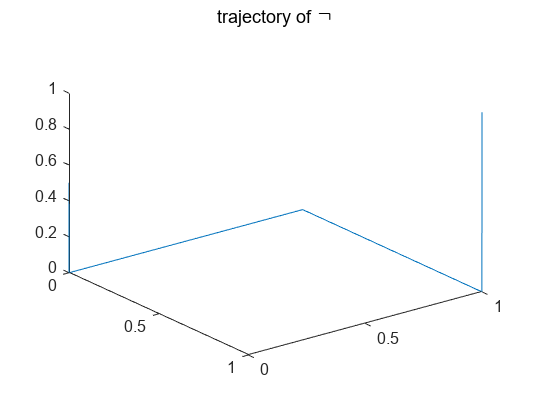

%%%Consonant Trajectory%%%%
% ㄱ
GField = [1 1]; %(xmax ymax) 단위: mm
tmax = (GField(1)+GField(2))/vmax;
t = 0:0.001:tmax+2;
Gx = (t-1).*heaviside(t-1)-(t-2).*heaviside(t-2);
Gy = (t-tmax/2-1).*heaviside(t-tmax/2-1)-(t-tmax-1).*heaviside(t-tmax-1);
Gz = 1-heaviside(t)+heaviside(t-tmax-1);
G = plot3(Gx, Gy, Gz);
set(gca, 'YDir','reverse')
title('trajectory of ㄱ')

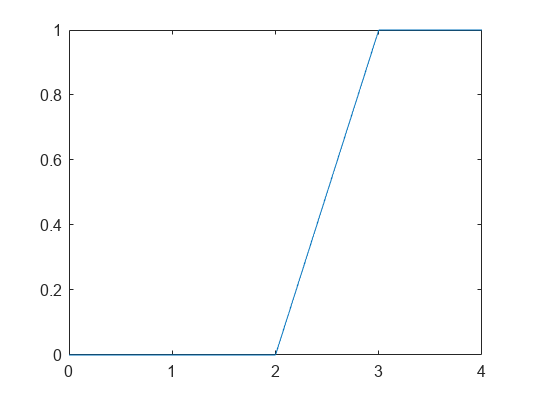

% ㄴ
GField = [1 1]; %(xmax ymax) 단위: mm
tmax = (GField(1)+GField(2))/vmax;
t = 0:0.001:tmax+2;
Nx = (t-tmax/2-1).*heaviside(t-tmax/2-1)-(t-tmax-1).*heaviside(t-tmax-1);
Ny = (t-1).*heaviside(t-1)-(t-tmax/2-1).*heaviside(t-tmax/2-1);
Nz = 1-heaviside(t)+heaviside(t-tmax-1);
plot(t, Nx)

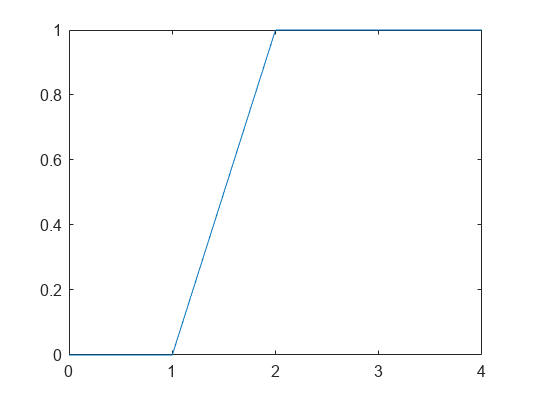

plot(t, Ny)

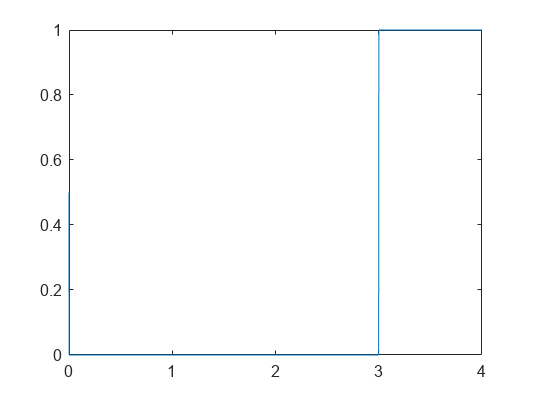

plot(t, Nz)

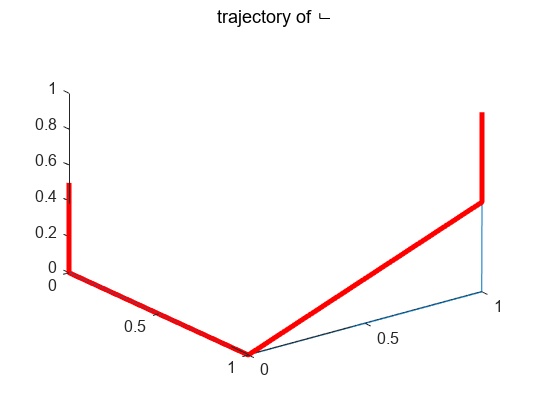

N = plot3(Nx, Ny, Nz);
set(gca, 'YDir','reverse')
title('trajectory of ㄴ')
h = animatedline('Color','r','LineWidth',3);
for k = 1:1000:length(t)
    addpoints(h,Nx(k),Ny(k),Nz(k));
    drawnow
end

%{
% ㄷ
numberOfStrokes = 3;
Dx = (ConsonantField(1,1)/(tmax/numberOfStrokes)).*t-(ConsonantField(1,1)/(tmax/numberOfStrokes)).*(t-(tmax/numberOfStrokes)).*heaviside(t-(tmax/numberOfStrokes))-(ConsonantField(1,1)/(tmax/numberOfStrokes)).*(t-2*(tmax/numberOfStrokes)).*heaviside(t-2*(tmax/numberOfStrokes));
Dy = (ConsonantField(1,2)/(tmax/numberOfStrokes)).*(t-(tmax/numberOfStrokes)).*heaviside(t-(tmax/numberOfStrokes))-(ConsonantField(1,2)/(tmax/numberOfStrokes)).*(t-2*(tmax/numberOfStrokes)).*heaviside(t-2*(tmax/numberOfStrokes));
D = plot(Dx, Dy);
set(gca, 'YDir','reverse')
title('trajectory of ㄷ')
h = animatedline('Color','r','LineWidth',3);
for k = 1:100:length(t)
    addpoints(h,Dx(k),Dy(k));
    drawnow
end

% ㄹ
numberOfStrokes = 5;
Rx = (ConsonantField(1,1)/(tmax/numberOfStrokes)).*t-(ConsonantField(1,1)/(tmax/numberOfStrokes)).*(t-(tmax/numberOfStrokes)).*heaviside(t-(tmax/numberOfStrokes))-(ConsonantField(1,1)/(tmax/numberOfStrokes)).*(t-2*(tmax/numberOfStrokes)).*heaviside(t-2*(tmax/numberOfStrokes))+(ConsonantField(1,1)/(tmax/numberOfStrokes)).*(t-3*(tmax/numberOfStrokes)).*heaviside(t-3*(tmax/numberOfStrokes))+(ConsonantField(1,1)/(tmax/numberOfStrokes)).*(t-4*(tmax/numberOfStrokes)).*heaviside(t-4*(tmax/numberOfStrokes));
Ry = (ConsonantField(1,2)/(tmax/numberOfStrokes))/2.*(t-(tmax/numberOfStrokes)).*heaviside(t-(tmax/numberOfStrokes))-(ConsonantField(1,2)/(tmax/numberOfStrokes))/2.*(t-2*(tmax/numberOfStrokes)).*heaviside(t-2*(tmax/numberOfStrokes))+(ConsonantField(1,2)/(tmax/numberOfStrokes))/2.*(t-3*(tmax/numberOfStrokes)).*heaviside(t-3*(tmax/numberOfStrokes))-(ConsonantField(1,2)/(tmax/numberOfStrokes))/2.*(t-4*(tmax/numberOfStrokes)).*heaviside(t-4*(tmax/numberOfStrokes));
R = plot(Rx, Ry);
set(gca, 'YDir','reverse')
title('trajectory of ㄹ')
h = animatedline('Color','r','LineWidth',3);
for k = 1:100:length(t)
    addpoints(h,Rx(k),Ry(k));
    drawnow
end

% ㅁ
numberOfStrokes = 4;
Mx = (ConsonantField(1,1)/(tmax/numberOfStrokes)).*t-(ConsonantField(1,1)/(tmax/numberOfStrokes)).*(t-(tmax/numberOfStrokes)).*heaviside(t-(tmax/numberOfStrokes))-(ConsonantField(1,1)/(tmax/numberOfStrokes)).*(t-2*(tmax/numberOfStrokes)).*heaviside(t-2*(tmax/numberOfStrokes))+(ConsonantField(1,1)/(tmax/numberOfStrokes)).*(t-3*(tmax/numberOfStrokes)).*heaviside(t-3*(tmax/numberOfStrokes));
My = (ConsonantField(1,2)/(tmax/numberOfStrokes)).*(t-(tmax/numberOfStrokes)).*heaviside(t-(tmax/numberOfStrokes))-(ConsonantField(1,2)/(tmax/numberOfStrokes)).*(t-2*(tmax/numberOfStrokes)).*heaviside(t-2*(tmax/numberOfStrokes))-(ConsonantField(1,2)/(tmax/numberOfStrokes)).*(t-3*(tmax/numberOfStrokes)).*heaviside(t-3*(tmax/numberOfStrokes));
M = plot(Mx, My);
set(gca, 'YDir','reverse')
title('trajectory of ㅁ')
h = animatedline('Color','r','LineWidth',3);
for k = 1:100:length(t)
    addpoints(h,Mx(k),My(k));
    drawnow
end

% ㅂ
numberOfStrokes = 4;
Bx = 
By = 
plot(t,Rx)
plot(t, Ry)
B = plot(Bx, By);
set(gca, 'YDir','reverse')
title('trajectory of ㅂ')

% ㅅ
numberOfStrokes = 2;
Sx = 
Sy = 
plot(t,Rx)
plot(t, Ry)
S = plot(Sx, Sy);
set(gca, 'YDir','reverse')
title('trajectory of ㅅ')

% ㅇ
numberOfStrokes = 1;
Ngx = -ConsonantField(1,1)/2.*cos(2*pi/tmax.*t)+ConsonantField(1,1)/2;
Ngy = -ConsonantField(1,2)/2.*sin(2*pi/tmax.*t)+ConsonantField(1,2)/2;
Ng = plot(Ngx, Ngy);
set(gca, 'YDir','reverse')
title('trajectory of ㅇ')
h = animatedline('Color','r','LineWidth',3);
for k = 1:100:length(t)
    addpoints(h,Ngx(k),Ngy(k));
    drawnow
end

% ㅈ
numberOfStrokes = 3;
Jx =
Jy =
plot(t,Rx)
plot(t, Ry)
J = plot(Jx, Jy);
set(gca, 'YDir','reverse')
title('trajectory of ㅈ')

% ㅊ
numberOfStrokes = 4;
Chx = 
Chy = 
plot(t,Rx)
plot(t, Ry)
Ch = plot(Chx, Chy);
set(gca, 'YDir','reverse')
title('trajectory of ㅊ')

% ㅋ
numberOfStrokes = 3;
Kx =
Ky =
plot(t,Rx)
plot(t, Ry)
K = plot(Kx, Ky);
set(gca, 'YDir','reverse')
title('trajectory of ㅋ')

% ㅌ
numberOfStrokes = 4;
Tx = 
Ty = 
plot(t,Rx)
plot(t, Ry)
T = plot(Tx, Ty);
set(gca, 'YDir','reverse')
title('trajectory of ㅌ')

% ㅍ
numberOfStrokes = 4;
Px = 
Py = 
plot(t,Rx)
plot(t, Ry)
P = plot(Px, Py);
set(gca, 'YDir','reverse')
title('trajectory of ㅍ')

% ㅎ
numberOfStrokes = 3;
Hx = -ConsonantField(1,1)/4.*cos(2*pi/(tmax/numberOfStrokes).*(t-2*(tmax/numberOfStrokes)).*heaviside(t-2*(tmax/numberOfStrokes)))+(3/4)*ConsonantField(1,1);
Hy = -ConsonantField(1,2)/4.*sin(2*pi/(tmax/numberOfStrokes).*(t-2*(tmax/numberOfStrokes)).*heaviside(t-2*(tmax/numberOfStrokes)))+(3/4)*ConsonantField(1,2);
plot(t,Hx)
plot(t, Hy)
H = plot(Hx, Hy);
set(gca, 'YDir','reverse')
title('trajectory of ㅎ')

%%%VerticalVowel Trajectory%%%%
% ㅏ
numberOfStrokes = 2;
Ax = 
Ay = 
plot(t,Rx)
plot(t, Ry)
A = plot(Ax, Ay);
set(gca, 'YDir','reverse')
title('trajectory of ㅏ')

% ㅑ
numberOfStrokes = 3;
Yax = 
Yay = 
plot(t,Rx)
plot(t, Ry)
Ya = plot(Yax, Yay);
set(gca, 'YDir','reverse')
title('trajectory of ㅑ')

% ㅓ
numberOfStrokes = 2;
Eox = 
Eoy = 
plot(t,Rx)
plot(t, Ry)
Eo = plot(Eox, Eoy);
set(gca, 'YDir','reverse')
title('trajectory of ㅓ')

% ㅕ
numberOfStrokes = 3;
Yeox = 
Yeoy = 
plot(t,Rx)
plot(t, Ry)
Yeo = plot(Yeox, Yeoy);
set(gca, 'YDir','reverse')
title('trajectory of ㅕ')

% ㅣ
numberOfStrokes = 1;
Ix = VerticalVowelField(1,1)/2.*t./t;
Iy = (VerticalVowelField(1,2)/(tmax/numberOfStrokes)).*t;
I = plot(Ix, Iy);
set(gca, 'YDir','reverse')
title('trajectory of ㅣ')
h = animatedline('Color','r','LineWidth',3);
for k = 1:100:length(t)
    addpoints(h,Ix(k),Iy(k));
    drawnow
end

%%%HorizontalVowel Trajectory%%%%
% ㅗ
numberOfStrokes = 2;
Ox = 
Oy = 
plot(t,Rx)
plot(t, Ry)
O = plot(Ox, Oy);
set(gca, 'YDir','reverse')
title('trajectory of ㅗ')

% ㅛ
numberOfStrokes = 3;
Yox = 
Yoy = 
plot(t,Rx)
plot(t, Ry)
Yo = plot(Yox, Yoy);
set(gca, 'YDir','reverse')
title('trajectory of ㅛ')

% ㅜ
numberOfStrokes = 2;
Ux = 
Uy = 
plot(t,Rx)
plot(t, Ry)
U = plot(Ux, Uy);
set(gca, 'YDir','reverse')
title('trajectory of ㅜ')

% ㅠ
numberOfStrokes = 3;
Yux = 
Yuy = 
plot(t,Rx)
plot(t, Ry)
Yu = plot(Yux, Yuy);
set(gca, 'YDir','reverse')
title('trajectory of ㅠ')

% ㅡ
numberOfStrokes = 1;
Eux = (HorizontalVowelField(1,1)/(tmax/numberOfStrokes)).*t;
Euy = HorizontalVowelField(1,2)/2.*t./t;
Eu = plot(Eux, Euy);
set(gca, 'YDir','reverse')
title('trajectory of ㅡ')
h = animatedline('Color','r','LineWidth',3);
for k = 1:100:length(t)
    addpoints(h,Eux(k),Euy(k));
    drawnow
end
%}